## Sensitivity analysis of frequency response of a 2dof oscillator

Reference: A. Saccani, J. Marconi & P. Tiso. *Sensitivity Analysis of Nonlinear Frequency Response of Defected Structures*, Nonlinear Dynamics. PREPRINT (Version 1) available at Research Square [https://doi.org/10.21203/rs.3.rs-1707949/v1](https://doi.org/10.21203/rs.3.rs-1707949/v1)

Author: Alexander Saccani, Msc in mechanical engineering, PoliMi

Created: 09/2021

close all
clear
clc

## Set input

% PARAMETER OF THE SYSTEM__________________________________________________
%masses:
m1 = 1; 
m2 = 1;

%springs:  k_ij : i-> dof, j-> exponent of force     
k11 = 1;
k13 = 1;
k21 = 1;
k23 = 1;

%damping:
d1 = 0.2;
d2 = 0.2;

%load:
F = 1;

% DEFINITION OF PARAMETER VECTOR AND ITS VARIATION_________________________
% with reference to the attached pdf file we define the parameter vector 
% with respect to sensitivity analysis is performed. We define its nominal
% value and its variation from the nominal.

% parameter nominal value
p = [k11, k13, k21, k23, m1, m2, d1, d2]';

% percentage parameter variation
dp_perc = [-10, -10, -10, -10, +20, +20, +30 , +30]';

% actual parameter variation
dp = p.*dp_perc/100;

% ANALYSIS SETTINGS________________________________________________________
H = 5;              % number of harmonics
method = 'normal';  % method for sensitivity analysis
ord_exp = 2;        % expansion order for sensitivity analysis

## Nominal solution and sensitivity analysis

% nominal solution is computed simulating the system for parameter
% vector p. Sensitivity analysis to parameters is run in parallel with the
% nominal solution

%length of parameter vector
m = length(p);

%number of dofs
n = 2;

% CREATE SYSTEM FOR NLvib__________________________________________________
%1st cubic spring
nonlinear_elements{1} = struct('type', 'cubicspring',...
    'stiffness', k13, 'force_direction', [1;0]);

%2nd cubic spring
nonlinear_elements{2} = struct('type', 'cubicspring',...
    'stiffness', k23, 'force_direction', [1;-1]);

%generate system
system = ChainOfOscillators([m1,m2],[d1,d2,0],[k11,k21,0],...
    nonlinear_elements,[F,0]);

% EIGENVALUE ANALYSIS _____________________________________________________
%stiffness matrix
K = system.K;

%mass matrix
M = system.M;

%eigenvalue analysis
[~,om] = eigs(K, M, 2, 'SM');
[om_n,~] = sort(sqrt(diag(om)));

% SET PARAMETERS FOR ANALYSIS______________________________________________
% natural frequency of interest
foi = 1; 

% set frequency range for analysis
Om_s = .2*om_n(foi);    % start frequency
Om_e = 4*om_n(foi);     % end frequency 

% number of samples for A.F.T.
N = 3*H+1;	% for residual of nonlinear forces 
Ns = 2*N;	% for derivatives of the residual (usually this value has to be
            % greater then N)

% initial guess for continuation (linear approximation)
Q1 = (-Om_s^2*system.M + 1i*Om_s*system.D + system.K)\[F,0]';
x0 = zeros((2*H+1)*length(Q1),1);
x0(length(Q1)+(1:2*length(Q1))) = [real(Q1);-imag(Q1)]; 

% define function handle for derivatives in time domain
derFunHandle = @(q)twoDof_forces_der(q,p);

% define postprocessing function for sensitivity analysis
fun_postprocess = @(X)HB_sensitivity(X, system, derFunHandle, m, method,...
                                    ord_exp, Ns);
% define path continuation step size
ds = .01;

% other settings for continuation
Solopt = optimset(optimset(@fsolve),'Display','off',...
        'Jacobian','on');
Sopt = struct('jac','on'); % analytical Jacobian provided here

% RUN ANALYSIS_____________________________________________________________

[Xnom,SolInfo,Sol] = solve_and_continue(x0,...
    @(X) HB_residual(X,system,H,N), Om_s, Om_e, ds, ...
     Sopt, fun_postprocess, Solopt); 

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1        0.752546                          3.82               1
     1          2       0.0215477       0.343272          0.474               1
     2          3     6.15259e-05      0.0863793         0.0225               1
     3          4     9.56926e-10     0.00510936       7.88e-05               1
     4          5     4.34204e-19    2.44037e-05       1.49e-09               1




% decode nominal solution
Xn = nlvib_decode(Xnom, SolInfo, Sol, 'FRF', 'HB', n, H);

% Xn is a struct array with fields 'Q0','Qre','Qim','omega'. 
% Xn.Q0{ij} --> static coefficient A0,  dof i, sample j
% Xn.Qre{ijk} --> real coefficient, dof i, sample j, harmonic k
% Xn.Qim{ijk} --> imaginary coefficient, dof i, sample j, harmonic k
% Xn.omega --> vector of ang. frequencies

% compute RMS for harmonics [0,2,3,4,5]
harm = [0, 2:H];
Xn.RMS = RMS(Xn,harm);

% create struct array with sensitivities
sens = [Sol.Sens];

## Sensitivity based solution

% response for p = p + dp computed with 1st and 2nd order sensitivities
X12 = update_response(Xnom, sens, dp);

% decode sensitivity based response
X1 = nlvib_decode(X12.lin,  0, 0, 'FRF', 'HB', n, H); % linear approx.
X2 = nlvib_decode(X12.quad, 0, 0, 'FRF', 'HB', n, H); % quadratic approx.

%compute RMS for harmonics [0,2,3,4,5]
harm = [0, 2:H];
X1.RMS = RMS(X1, harm);
X2.RMS = RMS(X2, harm);

## Re-simulate the system for p = p+dp

% UPDATE SYSTEM FOR NlVib _________________________________________________

% update stiffness values
k11 = k11 + dp(1);
k13 = k13 + dp(2);
k21 = k21 + dp(3);
k23 = k23 + dp(4);
m1 = m1 + dp(5);
m2 = m2 + dp(6);
d1 = d1 + dp(7);
d2 = d2 + dp(8);

% 1st cubic spring
nonlinear_elements{1} = struct('type', 'cubicspring',...
    'stiffness', k13, 'force_direction', [1;0]);

% 2nd cubic spring
nonlinear_elements{2} = struct('type', 'cubicspring',...
    'stiffness', k23, 'force_direction', [1;-1]);

% generate system
system = ChainOfOscillators([m1,m2], [d1,d2,0], [k11,k21,0], ...
    nonlinear_elements, [F,0]);

% EIGENVALUE ANALYSIS _____________________________________________________
% stiffness matrix
K = system.K;

% mass matrix
M = system.M;

% eigenvalue analysis
[VMn,om] = eigs(K, M, 2, 'SM');
[om_n,ind] = sort(sqrt(diag(om)));

% RUN ANALYSIS_____________________________________________________________

% initial guess for continuation (linear approximation)
Q1 = (-Om_s^2*system.M + 1i*Om_s*system.D + system.K)\[F,0]';
x0 = zeros((2*H+1)*length(Q1),1);
x0(length(Q1)+(1:2*length(Q1))) = [real(Q1);-imag(Q1)]; 

% % set frequency range for analysis
% Om_s = .2*om_n(foi);	% start frequency
% Om_e = 4*om_n(foi);     % end frequency 

% re-simulate the system
[X,SolInfo,Sol] = solve_and_continue(x0,...
    @(X) HB_residual(X,system,H,N), Om_s, Om_e, ds); 

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1         1.22077                          5.03               1
     1          2       0.0435499        0.41511          0.664               1
     2          3     0.000259234       0.145831         0.0437            1.04
     3          4     4.46477e-08      0.0218795       0.000505            1.04
     4          5     1.63689e-15    0.000270031       8.52e-08            1.04




% decode re-simulated solution
Xr = nlvib_decode(X, SolInfo, Sol, 'FRF', 'HB', n, H);

% compute RMS
Xr.RMS = RMS(Xr,harm);

## Plot results

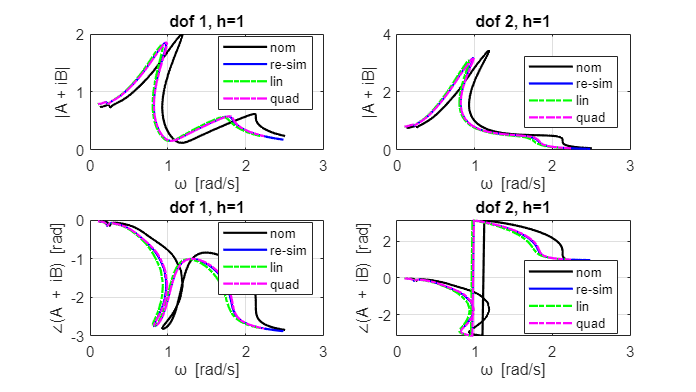

% input of 'plot_frc1.m'. which curve to plot?
frc_data = {Xn, Xr, X1, X2};

% input of 'plot_frc1.m'. for more details look function description
items2plot.subplot = [221 222 223 224];
items2plot.object = {'mod', 'mod', 'phase', 'phase'};
items2plot.dof = [1 2 1 2];
items2plot.harm = [1 1 1 1];
% input of 'plot_frc1.m'. for more details look function description
plotOptions.legend = {'nom', 're-sim', 'lin', 'quad'};
plotOptions.color = {'k', 'b', 'g', 'm'};
plotOptions.lineWidth = {1.5 1.5 1.5 1.5};
plotOptions.lineStyle = {'-','-','-.','-.'};
plotOptions.marker = {'none', 'none', 'none', 'none'};
plotOptions.fontSize = 10;

% plot modulus of first harmonic, dof 1 and 2 and RMS of harm 0,2,3,5
figure('units','normalized','position',[.2 .2 .6 .6])
plot_FRC(frc_data, items2plot, plotOptions);

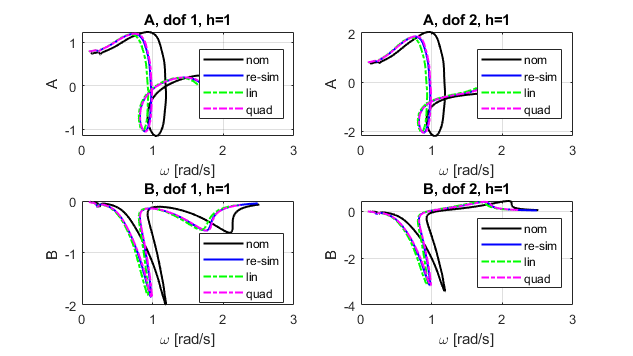

% plot coefficients A & B
items2plot.object = {'A', 'A', 'B', 'B'};
figure('units','normalized','position',[.2 .2 .6 .6])
plot_FRC(frc_data, items2plot, plotOptions);

#### FUNCTIONS

function der = twoDof_forces_der(q,p)

%set input
q1 = q(1); q2 = q(2);

%parameter names
k11 = p(1); k13 = p(2); k21 = p(3); k23 = p(4);
m1 = p(5);  m2 = p(6);
d1 = p(7);  d2 = p(8);

% define derivatives
% dfdq (only nonlinear forces in f)
dfdq = reshape([k13.*q1.^2.*3.0+k23.*(q1-q2).^2.*3.0,k23.*(q1-q2).^2.*-...
    3.0,k23.*(q1-q2).^2.*-3.0,k23.*(q1-q2).^2.*3.0],[2,2]);

% dfdp (linear + nonlinear forces in f)
dfdp = reshape([q1,0.0,q1.^3,0.0,q1-q2,-q1+q2,(q1-q2).^3,-(q1-q2).^3,...
    0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0],[2,8]);

% dfdq2 (nonlinear forces, dfdq2 for linear forces is null)
dfdq2 = reshape([k13.*q1.*6.0+k23.*(q1.*2.0-q2.*2.0).*3.0,...
    k23.*(q1.*2.0-q2.*2.0).*-3.0,k23.*(q1.*2.0-q2.*2.0).*-3.0,...
    k23.*(q1.*2.0-q2.*2.0).*3.0,k23.*(q1.*2.0-q2.*2.0).*-3.0,...
    k23.*(q1.*2.0-q2.*2.0).*3.0,k23.*(q1.*2.0-q2.*2.0).*3.0,...
    k23.*(q1.*2.0-q2.*2.0).*-3.0],[2,2,2]);

% dfdp2 (linear + nonlinear forces)
dfdp2 = zeros(2,8,8);

% dfdpdq (linear + nonlinear forces)
dfdqdp = reshape([1.0,0.0,0.0,0.0,q1.^2.*3.0,0.0,0.0,0.0,1.0,-1.0,...
    -1.0,1.0,(q1-q2).^2.*3.0,(q1-q2).^2.*-3.0,(q1-q2).^2.*-3.0,...
    (q1-q2).^2.*3.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,...
    0.0,0.0,0.0,0.0],[2,2,8]);

% derivative of mass matrix dMdp_ijk   k -> number of parameter
% M = [m1 0; 0 m2];
dMdp = zeros(2,2,8);
dMdp(1,1,5) = 1;
dMdp(2,2,6) = 1;

% derivative of mass matrix dDdp_ijk   k -> number of parameter
% D = [d1+d2 -d2; -d2 d2]
dDdp = zeros(2,2,8);
dDdp(1,1,7) = 1;
dDdp(1,1,8) = 1;
dDdp(1,2,8) = -1;
dDdp(2,1,8) = -1;
dDdp(2,2,8) = 1;

%Notice that we didn't define dKdp. Indeed we took into account for this
%term in dfdp, dfdqdp. Anyway it is still possible to define dKdp and
%not introduce derivatives of linear stiffness terms in dfdp and dfdqdp. In
%this case add field .dKdp to output

% generate output in struct array
der.dfdq = dfdq;
der.dfdp = dfdp;
der.dfdq2 = dfdq2;
der.dfdp2 = dfdp2;
der.dfdqdp = dfdqdp;

der.dMdp = dMdp;
der.dDdp = dDdp;

end